# CAB420 Assignment 1

Authors: - Minh Nhat Tuong - Nguyen, n9776001 - Quang Huy Tran, n10069275

## Theory

Logistic regression is a method of fitting a probabilistic classifier that gives soft linear thresholds. It is common to use logistic regression with an objective/loss function consisting of the negative log probability of the data plus a L2 regularizer:


$$L(\textbf{w}) = -\displaystyle\sum_{i=1}^{N} Log \left( \frac{1}{1+e^{y_i \left( \textbf{w}^T \textbf{x}_i + b \right) }} \right) + \lambda \|\textbf{w}\|_2^2 $$


(Here w does not include the “extra” weight w0.)

(a) Find the partial derivatives $\frac{\partial L}{\partial w_j}$

Let $ u = 1 + e^{y_i \left( \textbf{w}^T \textbf{x} + b \right)} $, we have: $ L(\textbf{w}) = -\displaystyle\sum_{i=1}^{N} -log(u) + \lambda \|\textbf{w}\|_2^2 $

Hence,


$$ \frac{\partial L}{\partial \textbf{w}_j} = -\displaystyle\sum_{i=1}^{N} \frac{\partial}{\partial u} - log(u) \frac{\partial u}{\partial \textbf{w}_j} +  \frac{\partial}{\partial \textbf{w}_j} \lambda \|\textbf{w}\|_2^2 $$



$$ \frac{\partial}{\partial w_j} \lambda \|\textbf{w}\|_2^2 = 2 \lambda \textbf{w}_j $$



$$ \frac{\partial}{\partial u} -log(u) = \frac{-1}{u} $$



$$ \frac{\partial u }{\partial \textbf{w}_j} = y_i \textbf{x}_i e^{y_i(\textbf{w}^T \textbf{x}_i + b)} $$



$$ \frac{\partial L}{\partial \textbf{w}_j} = -\displaystyle\sum_{i=1}^{N} 2 \lambda \textbf{w}_j - \frac{y_i \textbf{x}_i e^{y_i(\textbf{w}^T _i + b)}}{1 + e^{y_i \left( \textbf{w}^T \textbf{x}_i + b \right)}} $$


b) Find the partial second derivatives $\frac{\partial L^2}{\partial w_j \partial w_k}$.

We have:

Let:

while:

Then:

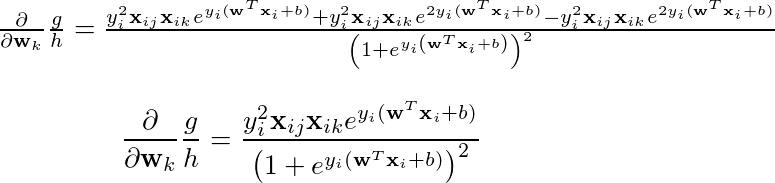

Hence,

(c) From these results, show that $L(w)$ is a convex function.

Function   is convex because its Hessian   is PSD. 

  can be shown to satisfy the criteria   because the output of all functions in the Hessian is always positive.

## 1. Features, Classes, and Linear Regression

Clean up

clc
clear
close all

disp('1. Features, Classes, and Linear Regression');

% (a) Plot the training data in a scatter plot.

% Load training dataset
% replace \ to load file on windows
mTrain = load('data/mTrainData.txt');

% Separate features
Xtr = mTrain(: ,1); % X = single feature
Ytr = mTrain(: ,2); % Y = target value
whos

% Plot training data
figure('name', 'Training Data');
plot (Xtr, Ytr, 'bo'); 
xlabel('x');
ylabel('y');
title('Plotting all training data points');
legend('Training data');

(b) Create a linear regression learner using the above functions. Plot it on the same plot as the training data.

linXtr = polyx(Xtr, 1);
learner_linear = linearReg(linXtr, Ytr);
xline = [0:.01:1]'; % Transpose
yline = predict(learner_linear, polyx(xline, 1));

figure('name', 'Linear regression predictor');
plot(xline, yline);
hold on % Plot training data and label figure.
plot (Xtr, Ytr, 'bo');
legend('Linear Predictor','Training data');
xlabel('x');
ylabel('y');
title('Linear regression predictor');

Alternative quadratic predictor.

quadXtr = polyx(Xtr, 2);
learner_quadratic = linearReg(quadXtr, Ytr); % Create and learn a regression predictor from the data Xtr, ytr.
xline = [0:.01:1]' ; % Transpose
yline = predict(learner_quadratic, polyx(xline, 2)); % Assuming quadratic features
figure('name', 'Quadratic linear predictor');
plot(xline, yline);
hold on % Plot training data and label figure.
plot (Xtr, Ytr, 'bo');
legend('Linear Predictor', 'Training Data');
title('Quadratic linear predictor');

(c) Create plots with the data and a higher-order polynomial (3, 5, 7, 9, 11, 13).

quinXtr = polyx(Xtr, 5);
learner_quintic = linearReg (quinXtr , Ytr);
yline = predict (learner_quintic , polyx(xline ,5)); % assuming quintic features
figure('name', 'Quintic linear predictor');
plot ( xline , yline );
hold on
plot (Xtr, Ytr, 'bo');
legend('Linear Predictor', 'Training Data');
title('Quintic linear predictor');

(d) Calculate the mean squared error associated with each of your learned models on the training data. Linear

yhat = predict(learner_linear, linXtr);
mseLinTrain = immse(yhat, Ytr);
fprintf('The MSE for the linear predictor on training data was: %.4f\n', mseLinTrain);

% Quadratic
yhat = predict(learner_quadratic, quadXtr);
mseQuadTrain = immse(yhat, Ytr);
fprintf('The MSE for the quadratic linear predictor on training data was: %.4f\n', mseQuadTrain);

% Quintic
yhat = predict(learner_quintic, quinXtr);
mseQinTrain = immse(yhat, Ytr);
fprintf('The MSE for the quintic linear predictor on training data was: %.4f\n', mseQinTrain);

(e,f,g) Calculate the MSE for each model on the test data (in mTestData.txt). Compare the obtained MAE values with the MSE values obtained above.

mTest = load('data/mTestData.txt');
xtest = mTest(: ,1); ytest = mTest(: ,2);
% Linear
Xtest = polyx(xtest, 1);
yhat = predict(learner_linear, Xtest);
mseLinTest = immse(yhat, ytest);
fprintf('The MSE for the linear predictor on test data was: %.4f\n', mseLinTest);
% Quadratic
Xtest = polyx(xtest, 2);
yhat = predict(learner_quadratic, Xtest);
mseQuadTest = immse(yhat, ytest);
fprintf('The MSE for the quadratic linear predictor on test data was: %.4f\n', mseQuadTest);
% Quintic
Xtest = polyx(xtest, 5);
yhat = predict(learner_quintic, Xtest);
mseQuinTest = immse(yhat, ytest);
fprintf('The MSE for the quintic linear predictor on test data was: %.4f\n', mseQuinTest);

## 2. kNN Regression

(a) Using the knnRegress class, implement (add code to) the predict function to make it functional.

(b) Using the same technique as in Problem 1a, plot the predicted function for several values of $k: 1, 2, 3, 5, 10, 50$. How does the choice of $k$ relate to the ?complexity? of the regression function?

kV = [1,2,3,5,10,50];  % K values of Problem 2 
xline = [0:.01:1]'; % transpose 
figure('Name','Plot the KNN Regression Prediction for different polynomials');
for i = 1:length(kV)
    learner = knnRegress(kV(i),Xtr,Ytr);
    yline = predict(learner,xline);
    subplot(3,2,i); 
    plot(xline,yline,'b');
    title(['k = ',num2str(kV(i))]);
    xlabel('Features');
    ylabel('Labels');
end

(c) What kind of functions can be output by a nearest neighbor regression function? Briefly justify your conclusion.

% Based on the plot of 2b, it can be observed that the output of a nearest 
% neighbor regression function is a linear function

## 3. Hold-out and Cross-validation

**(a) Similarly to Problem 1 and 2, compute the MSE of the test data on a model trained on only the first 20 training data examples for** $k = 1, 2, 3, . . . , 140$**. Plot the MSE versus** $k$** on a log-log scale (see help loglog).**

%Clean up
clc
clear
close all

%Import data
mTrain = load('data/mTrainData.txt');
mTest = load('data/mTestData.txt');
xtest = mTest(: ,1); % Features
ytest = mTest(: ,2); % Values

% first 20 training data examples
xtr = mTrain(1:20,1);
ytr = mTrain(1:20,2); 
 
% initalise a vector for MSE of each k value
MSE1 = zeros(140, 1); 

for k=1:140 % iterate on each k value
    learner = knnRegress(k, xtr, ytr); % create the learner using k
    yhat = predict(learner, xtest); % predict and find MSE relative to test data
    MSE1(k) = mean((yhat - ytest).^2);
end 
figure;
loglog(1:140, MSE1, 'r'); % plot on a loglog graph
xlabel('K value');
ylabel('MSE');
title('MSE on different K values');
legend('Only using first 20 training data examples');

**(b) Repeat, but use all the training data. What happened? Contrast with your results from problem 1 (hint: which direction is complexity in this picture?).**

% all training data examples
xtr = mTrain(:,1);
ytr = mTrain(:,2); 

% initalise a vector for MSE of each k value
MSE2 = zeros(140, 1); 

for k=1:140 % iterate on each k value
    learner = knnRegress(k, xtr, ytr); % create the learner using k
    yhat = predict(learner, xtest); % predict and find MSE relative to test data
    MSE2(k) = mean((yhat - ytest).^2);
end 

figure;
loglog(1:140, MSE1, 'r'); % plot on a loglog graph
xlabel('K value');
ylabel('MSE');
title('MSE on different K values');
hold on;
loglog(1:140, MSE2, 'b'); % plot on the loglog graph
legend('Only using first 20 training data examples', ...
    'All training data examples');
%
% _When using all training data, the MSE was able to be reduced much
% further.Contrast to problem 1, here we are increasing the complexity  of
% the sample (or training data) to reduce cost. Whereas in problem one we
% increased the model complexity by raising to 5th degree polynomial._
%

**(c) Using only the training data, estimate the curve using 4-fold cross-validation. Split the training data into two parts, indices 1:20 and 21:140; use the larger of the two as training data and the smaller as testing data, then repeat three more times with different sets of 20 and average the MSE. Add this curve to your plot. Why might we need to use this technique?**

hold on 
MSE3 = zeros(140, 1); % initalise a vector for MSE of each k value
for k=1:140 % test for 100 values of k
    MSEtemp = zeros(4, 1); % temp mse array for each i (averaged for each k)
    for i=1:4
        m = i*20; n = m-19; % local bounds
        iTest = mTrain(n:m,:); % 20 indicies for testing
        iTrain = setdiff(mTrain, iTest, 'rows'); % rest for training
        learner = knnRegress(k, iTrain(:,2), iTrain(:,1)); % train the learner
        yhat = predict(learner, iTest(:,2)); % predict at testing x values
        MSEtemp(i) = mean((yhat - iTest(:,1)).^2); 
    end
    MSE3(k) = mean(MSEtemp); % average the MSE 
end
loglog(1:140, MSE3, 'm'); % plot on the loglog graph
legend('Only using first 20 training data examples', ...
    'All training data examples', ...
    'All training data examples with 4-fold Cross-validation');
%
% _Using this technique may produce more accurate error values. This is
% because the effective 'testing data' changes multiple times per
% iteration, making it a better representation of the model. Also, in this
% case more data samples are used for testing because mTest only has 60
% samples relative to the 120 in mTrain.
%

## 4. Nearest Neighbor Classifiers

Load Iris Data

iris = load('data/iris.txt');
pi = randperm( size (iris ,1));
Y_iris = iris(pi ,5); X_iris = iris(pi ,1:2);

**(a) Plot the data by their feature values, using the class value to select the color.**

classes_iris = unique(Y_iris); % The number of iris classes 
colorString = ['b','g','r'];
figure('Name','Plot the data by the feature values');
for i = 1:length(classes_iris)
    index_feature = find(Y_iris==classes_iris(i));
    scatter(X_iris(index_feature,1),X_iris(index_feature,2),'filled',colorString(i));

    hold on 
end
legend('Class = 0','Class = 1','Class = 2');

**(b) Use the provided knnClassify class to learn a 1-nearest-neighbor predictor.**

knn1_classifier = knnClassify(1,X_iris,Y_iris);
class2DPlot(knn1_classifier,X_iris,Y_iris);

**(c) Do the same thing for several values of k (say, [1, 3, 10, 30]) and comment on their appearance.**

kValues = [1,3,10,30]; % K values of Problem 4

for i = 1:length(kValues)
    learner = knnClassify(kValues(i),X_iris,Y_iris);
    class2DPlot(learner,X_iris,Y_iris);
    title(strcat('k = ', num2str(kValues(i)))); 
end

**(d) Now split the data into an 80/20 training/validation split. For** $k = [1, 2, 5, 10, 50, 100, 200]$**, learn a model on the 80% and calculate its performance (# of data classified incorrectly) on the validation data. What value of k appears to generalize best given your training data? Comment on the performance at the two endpoints, in terms of over- or under-fitting.**

[Nx,Dx] = size(X_iris); 
Xtrain = X_iris(1:round(Nx*0.8),:); 
Ytrain = Y_iris(1:round(Nx*0.8)); 
Xvalid = X_iris(round(Nx*0.8)+1:end,:); 
Yvalid = Y_iris((round(Nx*0.8)+1):end); 
kvalues = [1,2,5,10,50,100,200]; 
err = zeros(length(kvalues)); 
for i = 1:length(kvalues)
    learner = knnClassify(kvalues(i), Xtrain,Ytrain); 
    Yhat = predict(learner,Xvalid); 
    err(i) = sum(Yhat~=Yvalid)/length(Yvalid); 
end 
figure(); 
plot(kvalues,err,'r');
xlabel('k'); ylabel('Error Rate'); 
title('Plot the performance of different k values of KNN Classification'); 

% After calculating the performance on the error rate of different 
% nearest neighbor classifier models using 80/20 training/validation split several times, 
% the values k = 5, 10 and 50 appears to generalize best given the training data. From the plot of error rates versus k values, 
% the performance at the two endpoints is over-fitting.

## 5. Perceptron and Logistic Regression

% Clean up*
clear;
clc;
close all;
% Load the Iris dataset 
iris = load('data/iris.txt'); 
X = iris(:,1:2); Y = iris(:, end); 
[X Y] = shuffleData(X,Y); 
X = rescale(X); 
XA = X(Y < 2, :); YA = Y(Y < 2); % get class 0 and 1
XB = X(Y > 0, :); YB = Y(Y > 0);

*(a) Show the two classes in a scatter plot and verify that one is linearly separable while the other is not

figure(); 

%Plot the dataset A having class 0 and 1 
subplot(1,2,1); 
posA = find(YA == 1); negA = find(YA == 0); 

plot(XA(posA,1), XA(posA,2), 'k+','LineWidth', 2,'MarkerSize',7); 
hold on 
plot(XA(negA,1), XA(negA,2),'ko', 'MarkerFaceColor', 'y', 'MarkerSize',7); 
hold off 
legend('Class = 1', 'Class = 0'); 
title('Class 0 vs Class 1 (Separable)');
xlabel('Sepal Length');
ylabel('Sepal Width');

%Plot the dataset B having class 1 and 2 
subplot(1,2,2); 
posB = find(YB == 2); negB = find(YB == 1); 
xlabel('Sepal Length');
ylabel('Sepal Width');
plot(XB(posB,1), XB(posB,2), 'k+','LineWidth', 2,'MarkerSize',7); 
hold on 
plot(XB(negB,1), XB(negB,2),'ko', 'MarkerFaceColor', 'y', 'MarkerSize',7); 
hold off 
legend('Class = 2', 'Class = 1'); 
title('Class 1 vs Class 2 (Non-Separable)');
xlabel('Sepal Length');
ylabel('Sepal Width');

**(b) Write (fill in) the function @logisticClassify2/plot2DLinear.m so that it plots the two classes of data in di?erent colors, along with the decision boundary (a line). Include the listing of your code in your report. To demo your function plot the decision boundary corresponding to the classifier** $$ sign(.5 + 1x_1 - .25x_2) $$

wts = [0.5 1 -0.25]; % Set weights 
 
%Logistic Classification of Dataset A 
learner_XA = logisticClassify2(); 
learner_XA = setClasses(learner_XA, unique(YA)); 
learner_XA = setWeights(learner_XA, wts);
plot2DLinear(learner_XA,XA,YA);     %Plot the linear decision boundary line of dataset A 
title('Linear decision boundary line of dataset A'); 
legend('Class = 0', 'Class = 1', 'Decision Boundary Line');

%Logistic Classification of Dataset B 
learner_XB = logisticClassify2(); 
learner_XB = setClasses(learner_XB, unique(YB)); 
learner_XB = setWeights(learner_XB, wts);
plot2DLinear(learner_XB,XB,YB);      %Plot the linear decision boundary line of dataset B
title('Linear decision boundary line of dataset B'); 
legend('Class = 1', 'Class = 2', 'Decision Boundary Line');

**(c) Complete the predict.m function to make predictions for your linear classifier.** Predict the labels of dataset A and computing error 

YA_pred = predict(learner_XA,XA); 
learnerA_error = 0; 
for i = 1:length(YA_pred)
    if( YA_pred(i) ~= YA(i))
        learnerA_error  =  learnerA_error + 1; 
    end 
end 
error_rate_A = learnerA_error/length(YA_pred); 
fprintf("\nThe error rate of dataset A is %.4f\n",error_rate_A);

% Predict the labels of dataset B and computing error 
YB_pred = predict(learner_XB,XB); 
learnerB_error = 0; 
for i = 1:length(YB_pred)
    if( YB_pred(i) ~= YB(i))
        learnerB_error  =  learnerB_error + 1; 
    end 
end 
a = err(learner_XB,XB,YB); 
error_rate_B = learnerB_error/length(YB_pred); 
fprintf("\nThe error rate of dataset B is %.4f\n",error_rate_B);

**(d)** Derive the gradient of the regularized negative log likelihood $J_j$ for logistic regression 


$$J_j^{\left(\theta \right)} =-y^{\left(j\right)} \mathrm{log}\sigma \left(\theta x^{j^T } \right)-\left(1-y^j \right)\mathrm{log}\left(1-\sigma \left(\theta x^{j^T } \right)\right)+\alpha \sum_i \theta_i^2$$



$$\frac{\partial }{\partial \theta_j }J_j^{\left(\theta \right)} =-\frac{\partial }{\partial \theta_j }\;y^{\left(j\right)} \mathrm{log}\sigma \left(\theta x^{j^T } \right)-\frac{\partial }{\partial \theta_j }\left(1-y^j \right)\mathrm{log}\left(1-\sigma \left(\theta x^{j^T } \right)\right)+\frac{\partial }{\partial \theta_j }\;\alpha \sum_i \theta_i^2 \;$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\left\lbrack \frac{y^{\left(j\right)} }{\sigma \left(\theta x^{j^T } \right)}-\frac{{1-y}^{\left(j\right)} }{1-\sigma \left(\theta x^{j^T } \right)}\right\rbrack$$

$$\frac{\partial }{\partial \theta_j }\sigma \left(\theta x^{j^T } \right)+2\alpha \theta_j$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\left\lbrack \frac{y^{\left(j\right)} }{\sigma \left(\theta x^{j^T } \right)}-\frac{{1-y}^{\left(j\right)} }{1-\sigma \left(\theta x^{j^T } \right)}\right\rbrack \sigma \left({\theta x}^{j^T } \right)\left\lbrack 1-\sigma \left({\theta x}^{j^T } \right)\right\rbrack x_j +2\alpha \theta_j$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\left\lbrack \frac{y^{\left(j\right)} -\sigma \left(\theta x^{j^T } \right)}{\sigma \left({\theta x}^{j^T } \right)\left\lbrack 1-\sigma \left({\theta x}^{j^T } \right)\right\rbrack x_j }\right\rbrack \sigma \left({\theta x}^{j^T } \right)\left\lbrack 1-\sigma \left({\theta x}^{j^T } \right)\right\rbrack x_j +2\alpha \theta_j$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\left\lbrack y^{\left(j\right)} -\sigma \left(\theta x^{j^T } \right)\right\rbrack x_j +2\alpha \theta_j$$


**(f) Run your logistic regression classifier on both data sets (A and B); for this problem, use no regularization** $(\alpha = 0)$**. Describe your parameter choices (stepsize, etc.) and show a plot of both the convergence of the surrogate loss and error rate, and a plot of the final converged classifier with the data (using e.g. plotClassify2D). In your report, please also include the functions that you wrote (at minimum, train.m, but possibly a few small helper functions as well)**

% Parameters
% -Step size of gradient ('stepsize'): 0.01 
% -Tolerance of stopping criterion ('stepTol'): 0.01 
% -Number of iterations ('stopIter'): 100 

% Training the dataset A 
train(learner_XA,XA,YA,'stepsize',0.01,'stepTol',0.01,'stopIter',100);

%Training the dataset B
train(learner_XB,XB,YB,'stepsize',0.01,'stepTol',0.01,'stopIter',100);

% Functions of train.m and logistic.m 

% logistic.m 

% function value = logistic(obj, X)
% % logistic(obj,X): evaluate the logistic function for weights obj.wts, data X
% % wts is (1 x d+1), X is (n x d)  : d features, n data points
% %
%   [n,d] = size(X);
%   X = [ones(n,1), X];      % extend features X by the constant feature
%   f = X * obj.wts' ;       % compute weighted sum of features
%   value = 1./(1+exp(-f));  % evaluate logistic function of weighted sum

% train.m 

% function obj = train(obj, X, Y, varargin)
% % obj = train(obj, Xtrain, Ytrain [, option,val, ...])  : train logistic classifier
% %     Xtrain = [n x d] training data features (constant feature not included)
% %     Ytrain = [n x 1] training data classes 
% %     'stepsize', val  => step size for gradient descent [default 1]
% %     'stopTol',  val  => tolerance for stopping criterion [0.0]
% %     'stopIter', val  => maximum number of iterations through data before stopping [1000]
% %     'reg', val       => L2 regularization value [0.0]
% %     'init', method   => 0: init to all zeros;  1: init to random weights;  
% % Output:
% %   obj.wts = [1 x d+1] vector of weights; wts(1) + wts(2)*X(:,1) + wts(3)*X(:,2) + ...
% 
% 
%   [n,d] = size(X);            % d = dimension of data; n = number of training data
% 
%   % default options:
%   plotFlag = true; 
%   init     = []; 
%   stopIter = 1000;
%   stopTol  = 0.1;
%   reg      = 0.0;
%   stepsize = 1;
% 
%   i=1;                                       % parse through various options
%   while (i<=length(varargin)),
%     switch(lower(varargin{i}))
%     case 'plot',      plotFlag = varargin{i+1}; i=i+1;   % plots on (true/false)
%     case 'init',      init     = varargin{i+1}; i=i+1;   % init method
%     case 'stopiter',  stopIter = varargin{i+1}; i=i+1;   % max # of iterations
%     case 'stoptol',   stopTol  = varargin{i+1}; i=i+1;   % stopping tolerance on surrogate loss
%     case 'reg',       reg      = varargin{i+1}; i=i+1;   % L2 regularization
%     case 'stepsize',  stepsize = varargin{i+1}; i=i+1;   % initial stepsize
%     end;
%     i=i+1;
%   end;
% 
%   X1    = [ones(n,1), X];     % make a version of training data with the constant feature
% 
%   Yin = Y;                              % save original Y in case needed later
%   obj.classes = unique(Yin);
%   if (length(obj.classes) ~= 2) error('This logistic classifier requires a binary classification problem.'); end;
%   Y(Yin==obj.classes(1)) = 0;
%   Y(Yin==obj.classes(2)) = 1;           % convert to classic binary labels (0/1)
% 
%   if (~isempty(init) || isempty(obj.wts))   % initialize weights and check for correct size
%     obj.wts = randn(1,d+1);
%   end;
%   if (any( size(obj.wts) ~= [1 d+1]) ) error('Weights are not sized correctly for these data'); end;
%   wtsold = 0*obj.wts+inf;
% 
% % Training loop (SGD):
% iter=1; Jsur=zeros(1,stopIter); J01=zeros(1,stopIter); done=0; 
% fprintf("Traing Starts-----------------------------------\n"); 
% fprintf("------------------------------------------------\n");
% while (~done) 
%   step = stepsize/iter;               % update step-size and evaluate current loss values
%   Jsur(iter) = mean(-Y' * log(logistic(obj,X)) - (1-Y)' * log(1 - logistic(obj,X)) + reg * obj.wts * obj.wts');   %%% TODO: compute surrogate (neg log likelihood) loss
%   fprintf("At iteration i = %i, the error = %.2f\n",iter,Jsur(iter));  
%   fprintf("------------------------------------------------\n");
%   J01(iter) = err(obj,X,Yin) * 100;
%   if (plotFlag), switch d,            % Plots to help with visualization
%     case 1, fig(2); plot1DLinear(obj,X,Yin);  %  for 1D data we can display the data and the function
%     case 2, fig(2); plot2DLinear(obj,X,Yin);  %  for 2D data, just the data and decision boundary
%     otherwise, % no plot for higher dimensions... %  higher dimensions visualization is hard
%   end; end;
%   % fig(1); semilogx(1:iter, Jsur(1:iter),'b-',1:iter,J01(1:iter),'g-'); drawnow;
% 
%   for j=1:n,
%     % Compute linear responses and activation for data point j
%     %%% TODO ^^^
%     y = logistic(obj,X(j,:));  
%     
%     % Compute gradient:
%     %%% TODO ^^^
%     grad = - X1(j,:) * (Y(j) -y) + 2 * reg * obj.wts;  
% 
%     obj.wts = obj.wts - step * grad;      % take a step down the gradient
%   end;
%   done = 0; 
%   %%% TODO: Check for stopping conditions
%   % Stop training when the change of loss is not bigger than stopTol or running out of iterations 
%   if((iter >= 2 && abs(Jsur(iter) - Jsur(iter - 1)) < abs(stopTol)) || iter >= stopIter)
%      done = 1; 
%      fprintf("Stop training after %i iterations\n",iter); 
%      fprintf('Training Completed------------------------------\n');
%      fig(); semilogx(1:iter, Jsur(1:iter),'b-',1:iter,J01(1:iter),'g-'); title("Plot of the convergence of the surrogate loss and error rate"); legend('Loss Function','Error Rate (%)'); 
%   end 
%   
%   wtsold = obj.wts;
%   iter = iter + 1;  % Increments the iteration 
%   
% 
% end;

*(g) Implement the mini batch gradient descent on the logistic function complete in train_in_batches.m function

% Run the training in batches of both data sets (A and B) 

% Training in batches of data sets A 
train_in_batches(learner_XA,XA,YA,11);

% Training in batches of data sets B 
train_in_batches(learner_XB,XB,YB,11); 

% Functions of create_mini_batches.m and train_in_batches.m 

% create_mini_batches.m 

%function mini_batches = create_mini_batches(obj, X,y, batch_size )
% %UNTITLED3 Summary of this function goes here
% %   Detailed explanation goes here
% 
% data_values = [X,y];
% [Nx,Nd] = size(data_values);
% 
% pi = randperm(Nx);
% 
% data_values = data_values(pi,:);%TODO  shuffle your data
% n_mini_batches = round(Nx/batch_size);%TODO  based on your data and the batch size compute the number of batches
% mini_batches = zeros(batch_size,3,n_mini_batches);
% 
% for i = 1:n_mini_batches
%    %TODO extract the minibatch values
%    mini_batches(:,:,i) = data_values(((i-1)*batch_size+1):i*batch_size,:); 
% end
% 
% end

%train_in_batches.m 

% function obj = train_in_batches(obj, X, Y, batch_size, varargin)
% % obj = train(obj, Xtrain, Ytrain [, option,val, ...])  : train logistic classifier
% %     Xtrain = [n x d] training data features (constant feature not included)
% %     Ytrain = [n x 1] training data classes 
% %     'stepsize', val  => step size for gradient descent [default 1]
% %     'stopTol',  val  => tolerance for stopping criterion [0.0]
% %     'stopIter', val  => maximum number of iterations through data before stopping [1000]
% %     'reg', val       => L2 regularization value [0.0]
% %     'init', method   => 0: init to all zeros;  1: init to random weights;  
% % Output:
% %   obj.wts = [1 x d+1] vector of weights; wts(1) + wts(2)*X(:,1) + wts(3)*X(:,2) + ...
% 
% 
%   [n,d] = size(X);            % d = dimension of data; n = number of training data
% 
%   % default options:
%   plotFlag = true; 
%   init     = []; 
%   stopIter = 1000;
%   stopTol  = -1;
%   reg      = 0.0;
%   stepsize = 1;
% 
%   i=1;                                       % parse through various options
%   while (i<=length(varargin)),
%     switch(lower(varargin{i}))
%     case 'plot',      plotFlag = varargin{i+1}; i=i+1;   % plots on (true/false)
%     case 'init',      init     = varargin{i+1}; i=i+1;   % init method
%     case 'stopiter',  stopIter = varargin{i+1}; i=i+1;   % max # of iterations
%     case 'stoptol',   stopTol  = varargin{i+1}; i=i+1;   % stopping tolerance on surrogate loss
%     case 'reg',       reg      = varargin{i+1}; i=i+1;   % L2 regularization
%     case 'stepsize',  stepsize = varargin{i+1}; i=i+1;   % initial stepsize
%     end;
%     i=i+1;
%   end;
% 
%   X1    = [ones(n,1), X];     % make a version of training data with the constant feature
% 
%   Yin = Y;                              % save original Y in case needed later
%   obj.classes = unique(Yin);
%   if (length(obj.classes) ~= 2) error('This logistic classifier requires a binary classification problem.'); end;
%   Y(Yin==obj.classes(1)) = 0;
%   Y(Yin==obj.classes(2)) = 1;           % convert to classic binary labels (0/1)
% 
%   if (~isempty(init) || isempty(obj.wts))   % initialize weights and check for correct size
%     obj.wts = randn(1,d+1);
%   end;
%   if (any( size(obj.wts) ~= [1 d+1]) ) error('Weights are not sized correctly for these data'); end;
%   wtsold = 0*obj.wts+inf;
% 
% % Training loop (SGD):
% iter=1; Jsur=zeros(1,stopIter); J01=zeros(1,stopIter); done=0; 
% while (~done) 
%   step = stepsize/iter;               % update step-size and evaluate current loss values
%   Jsur(iter) = mean(-Y' * log(logistic(obj,X)) - (1-Y)' * log(1 - logistic(obj,X)) + reg * obj.wts * obj.wts');    %%% TODO: compute surrogate (neg log likelihood) loss
%   fprintf("At iteration i = %i, the error = %.2f\n",iter,Jsur(iter));  
%   fprintf("------------------------------------------------\n");
%   J01(iter) = err(obj,X,Yin);
% 
%   if (plotFlag), switch d,            % Plots to help with visualization
%     case 1, fig(2); plot1DLinear(obj,X,Yin);  %  for 1D data we can display the data and the function
%     case 2, fig(2); plot2DLinear(obj,X,Yin);  %  for 2D data, just the data and decision boundary
%     otherwise, % no plot for higher dimensions... %  higher dimensions visualization is hard
%   end; end;
%   mini_batches = create_mini_batches(obj,X,Y,batch_size);   %Create mini-batches data using create_mini_batches.m function 
%   number_of_batches = round(n/batch_size);      % Number of batches 
%   for j=1:number_of_batches,   %Loop through all batches of data 
%     % Compute linear responses and activation for minibatch j
%     %%% TODO ^^^
%     batch_data = mini_batches(:,:,i); 
%     X_data = batch_data(:,1:2); 
%     Y_data = batch_data(:,3); 
%     % Compute gradient:
%     %%% TODO ^^^ 
%     [N,D] = size(X_data);
%     X1_data = [ones(N,1) X_data];
%     for j=1:N,
%     % Compute linear responses and activation for data point j
%     %%% TODO ^^^
%         y = logistic(obj,X_data(j,:));  
% 
%         % Compute gradient:
%         %%% TODO ^^^
%         grad = -X1_data(j,:) * (Y_data(j)-y) + 2 * reg * obj.wts;  
% 
%         obj.wts = obj.wts - step * grad;      % take a step down the gradient
%     end;;  
% 
%   end;
% 
%   done = 0;
%   %%% TODO: Check for stopping conditions
%   if((iter >= 2 && abs(Jsur(iter) - Jsur(iter - 1)) < abs(stopTol)) || iter >= stopIter)
%      done = 1; 
%      fprintf("Stop training after %i iterations\n",iter); 
%      fprintf('Training Completed------------------------------\n');
%      fig(); semilogx(1:iter, Jsur(1:iter),'b-',1:iter,J01(1:iter),'g-'); title("Plot of the convergence of surrogate loss and error rate"); legend('Loss Function','Error Rate (%)'); 
%   end 
% 
%   wtsold = obj.wts;
%   iter = iter + 1;
% end;

close all